# 观测效果分析

clc;
clear;
close all;
rng('default');
addpath(genpath('./data'));
addpath(genpath('./func'));

args    % 参数加载

## 数据加载

%% 数据加载
disp('数据量较大，预计耗时2分钟')

数据量较大，预计耗时2分钟


% 传播数据
data_propagator_temp = load("Propagator.mat");                
data_propagator = {data_propagator_temp.tleStruct.PositionVelocity}';      % 提取位置信息
data_propagator = data_propagator(1:data_num);                               % 获取前100各卫星数据（取决于生成多少）
data_propagator = cellfun(@(x) table2array(x(:,1:6)), data_propagator, 'UniformOutput', false);    % 提取卫星信息，去除速度信息
clear data_propagator_temp;
% 绕飞数据
data_flyaround_temp = load("FlyAround.mat");                
data_flyaround = {data_flyaround_temp.tleStruct.PositionVelocity}';      % 提取位置信息
data_flyaround = data_flyaround(1:data_num);                               % 获取前100各卫星数据（取决于生成多少）
data_flyaround = cellfun(@(x) table2array(x(:,1:6)), data_flyaround, 'UniformOutput', false);    % 提取卫星信息，去除速度信息
clear data_flyaround_temp;
% 保持数据
data_geostationkeeping_temp = load("GEOStationKeeping.mat");     
data_geostationkeeping = {data_geostationkeeping_temp.tleStruct.PositionVelocity}';      % 提取位置信息
isempty_index = ~cellfun('isempty', data_geostationkeeping);
data_geostationkeeping = data_geostationkeeping(isempty_index);
data_geostationkeeping = cellfun(@(x) table2array(x(:,1:6)), data_geostationkeeping, 'UniformOutput', false);    % 提取卫星信息，去除速度信息
clear data_geostationkeeping_temp;
% 观测卫星数据
data_observation_temp = load("SatObservation.mat");
sma_observation = [data_observation_temp.tleStruct.SemiMajorAxis]';
data_observation = {data_observation_temp.tleStruct.PositionVelocity}';
% 时间序列存储
time_series = (1:height(data_observation{1}))';
data_observation = cellfun(@(x) table2array(x(:,1:6)), data_observation, 'UniformOutput', false);    % 提取卫星信息，去除速度信息
clear data_observation_temp;


## 数据组织

dict = containers.Map();
dict('flyaround') = 0;
dict('geostationkeeping') = 1;
dict('propagator') = 2;
lable_flyaround = zeros(size(data_flyaround))+dict('flyaround');
lable_geostationkeeping = zeros(size(data_geostationkeeping))+dict('geostationkeeping');
label_propagator = zeros(size(data_propagator))+dict('propagator');
datas = [data_propagator;data_flyaround;data_geostationkeeping];
labels = [label_propagator;lable_flyaround;lable_geostationkeeping];


## 观测片段生成

% 片段长度生成
view_angle = 60;
segments = cell(length(data_observation),1);
for i = 1:length(data_observation)
    pos_obs = data_observation{i};
    segment = struct();
    segment.length = [];
    segment.label = [];
    for j = 1:length(datas)
        pos_target = datas{j};
        [~,~,visible_length,~] = segmentVisible(pos_target, pos_obs, time_series, view_angle);
        segment_label = repmat(labels(j),length(visible_length),1);
        segment.length = [segment.length;visible_length];
        segment.label = [segment.label;segment_label];
    end
    segments{i} = segment;
end


## 观测片段长度分析

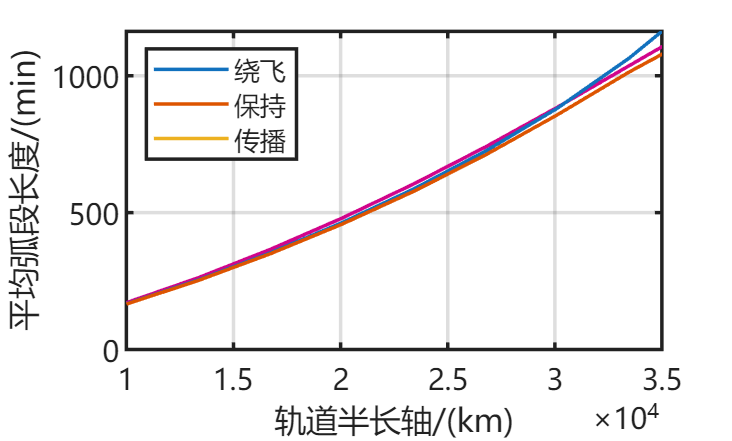

% 绘制随着观测卫星轨道高度变化，能够平均片段长度
time_step = 10;
mean_length_0 = cellfun(@(x) mean(x.length((x.label==0))), segments, 'UniformOutput', true);
mean_length_1 = cellfun(@(x) mean(x.length((x.label==1))), segments, 'UniformOutput', true);
mean_length_2 = cellfun(@(x) mean(x.length((x.label==2))), segments, 'UniformOutput', true);
myplot
plot(sma_observation,mean_length_0*time_step);
hold on;
plot(sma_observation,mean_length_1*time_step);
plot(sma_observation,mean_length_2*time_step);
legend('绕飞','保持','传播','Location','northwest')
xlabel('轨道半长轴/(km)')
ylabel('平均弧段长度/(min)')
xlim([1e4,3.5e4])

% clear segments 

## 观测片段生成

% 片段长度生成
view_angle = 60;
i = 5;
sma_obs = sma_observation(i);
pos_obs = data_observation{i};
isempty_index = find(isempty_index == 1);
isempty_index = [(1:length(data_propagator))';(1:length(data_flyaround))';isempty_index];
index = 1;
for j = 1:length(datas)
    pos_target = datas{j};
    [visible_segments,visible_time,visible_length] = segmentVisible(pos_target, pos_obs, time_series, view_angle);
    segment_label = repmat(labels(j),length(visible_length),1);
    segment_id = repmat(isempty_index(j),length(visible_length),1);
    for k = 1:length(visible_length)
        segment(index).length = visible_length(k);
        segment(index).label = segment_label(k);
        segment(index).id = segment_id(k);
        segment(index).position = visible_segments{k};
        segment(index).time = visible_time{k};
        index = index + 1;
    end
end


## 数据保存

%% 保存数据
save('./data/segments.mat', 'segment');